%% Newton-Raphson with linear diode model example

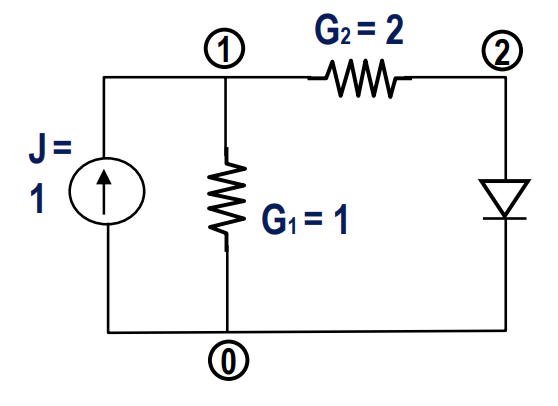


format long % display >4 decimal places

xMeaning = ["v_1"; "v_2"];

maxError = 0.0001;

% nodes
v_1 = 0

v_1 =      0


v_2 = 0

v_2 =      0


fprintf('\n')


i = 0;
while true
    x = NRIterate(v_1, v_2);
    
    v_1_old = v_1;
    v_2_old = v_2;
    
    i
    v_1 = x(1,1)
    v_2 = x(2,1)   
    fprintf('\n')
    
    if(abs(v_2 - v_2_old) < maxError)
        break;
    end
    
    i = i+1;
end

i =      0


v_1 =    0.999999999996001


v_2 =    0.999999999994001


i =      1


v_1 =    0.983333345130310


v_2 =    0.975000017695465


i =      2


v_1 =    0.966666742620253


v_2 =    0.950000113930379


i =      3


v_1 =    0.950000337545027


v_2 =    0.925000506317540


i =      4


v_1 =    0.933334618957278


v_2 =    0.900001928435917


i =      5


v_1 =    0.916671173427392


v_2 =    0.875006760141088


i =      6


v_1 =    0.900015010870483


v_2 =    0.850022516305724


i =      7


v_1 =    0.883381626416907


v_2 =    0.825072439625360


i =      8


v_1 =    0.866818073773779


v_2 =    0.800227110660668


i =      9


v_1 =    0.850464177227356


v_2 =    0.775696265841034


i =     10


v_1 =    0.834719753599336


v_2 =    0.752079630399003


i =     11


v_1 =    0.820627295717184


v_2 =    0.730940943575776


i =     12


v_1 =    0.810301768388072


v_2 =    0.715452652582108


i =     13


v_1 =    0.805702938273909


v_2 =    0.708554407410864


i =     14


v_1 =    0.804996543596639


v_2 =    0.707494815394958


i =     15


v_1 =    0.804982355524182


v_2 =    0.707473533286273


function x = NRIterate(v_1, v_2)
    I = 1; % current source
    
    % diode constants
    Is = 10e-14;
    Vt = 25e-3;

    % diode
    Vd = v_2;
    Gd = Is/Vt*exp(Vd/Vt);
    id = Is*(exp(Vd/Vt)-1) - Gd*Vd;
    
    G11 = 1+2;
    G12 = -2;
    G21 = -2;
    G22 = 2+Gd;
    
    A = [G11, G12; G21, G22];
    % A_inv = inv(A);
    
    b = [I; -id];
    
    x = A\b;
end

